# Handwritten Digit Recognizer

### Files needed

- handwritten_digit_recogniser.mlx

- data.mat

clear
dir

.                                 checkGradients.m                  displayData.m                     randInitializeWeights.m           
..                                computeNumericalGradient.m        fmincg.m                          sigmoid.m                         
CostFunction.m                    data.mat                          handwritten_digit_recogniser.mlx  sigmoidGradient.m                 
checkGradients.asv                debugInitializeWeights.m          predict.m                         weights.mat                       



### Visualizing data

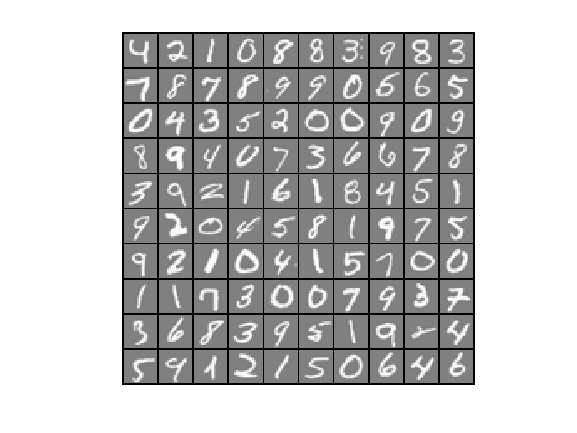

load('data.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));

### Feedforward Propagation

% Load the weights into variables Theta1 and Theta2
load('weights.mat');

*weights.mat *has a set of pre-trained parameters using which we implement the cost function and gradient for neural network.

*CostFunction.m *returns the cost.

input_layer_size  = 400;  % 20x20 Input Images of Digits
  hidden_layer_size = 25;   % 25 hidden units
  num_labels = 10;          % 10 labels, from 1 to 10 (note that we have mapped "0" to la
  % Unroll parameters
  params = [Theta1(:) ; Theta2(:)];
  % Weight regularization parameter (we set this to 0 here).
  lambda = 1;
  J = CostFunction(params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda) ;
fprintf('Cost at parameters (loaded from weights): %f', J);

Cost at parameters (loaded from weights): 0.383770

### Backpropagation

initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);
% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];

.

checkGradients;

   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
   -0.0002   -0.0002
    0.0002    0.0002
   -0.0003   -0.0003
    0.0003    0.0003
   -0.0004   -0.0004
   -0.0001   -0.0001
    0.0001    0.0001
   -0.0001   -0.0001
    0.0002    0.0002
   -0.0002   -0.0002
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1641    0.1641
    0.0576    0.0576
    0.0505    0.0505
    0.1646    0.1646
    0.0578    0.0578
    0.0508    0.0508
    0.1583    0.1583
    0.0559    0.0559
    0.0492    0.0492
    0.1511    0.1511
    0.0537    0.0537
    0.0471    0.0471
    0.1496    0.1496
    0.0532    0.0532
    0.0466    0.0466

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be

.

options = optimset('MaxIter', 50);
lambda = 1;

% Create "short hand" for the cost function to be minimized
costFunction = @(p) CostFunction(p, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the
% neural network parameters)
[params, ~] = fmincg(costFunction, initial_nn_params, options);

Iteration     1 | Cost: 3.283675e+00
Iteration     2 | Cost: 3.247938e+00
Iteration     3 | Cost: 3.202576e+00
Iteration     4 | Cost: 3.029417e+00
Iteration     5 | Cost: 2.646835e+00
Iteration     6 | Cost: 2.508508e+00
Iteration     7 | Cost: 2.137882e+00
Iteration     8 | Cost: 2.008393e+00
Iteration     9 | Cost: 1.790243e+00
Iteration    10 | Cost: 1.718561e+00
Iteration    11 | Cost: 1.641265e+00
Iteration    12 | Cost: 1.536956e+00
Iteration    13 | Cost: 1.490539e+00
Iteration    14 | Cost: 1.455129e+00
Iteration    15 | Cost: 1.348917e+00
Iteration    16 | Cost: 1.301253e+00
Iteration    17 | Cost: 1.288642e+00
Iteration    18 | Cost: 1.188402e+00
Iteration    19 | Cost: 1.163469e+00
Iteration    20 | Cost: 1.137756e+00
Iteration    21 | Cost: 1.048393e+00
Iteration    22 | Cost: 9.487068e-01
Iteration    23 | Cost: 9.122396e-01
Iteration    24 | Cost: 9.106424e-01
Iteration    25 | Cost: 8.645200e-01
Iteration    26 | Cost: 8.485105e-01
Iteration    27 | Cost: 8.388845e-01
I

% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 94.780000
